# Temperature Dependence of Fluorescence

Author: André Silva Correia

## Initialisation

LIFSIM_path = "C:\Users\andresilvacorr\OneDrive - Delft University of Technology\PhD\LIFSIM\LIFSim";
init;

### Species

species = "NO";
colls_path = "LIFSim\input-data\gas-compositions\air+NO.csv";

### Flame Characteristics

    Tflame - flame temperature profile at different $\phi$

    Y_species - target species molar concentration

    phi - equivalenc ratio $\phi$

load("input-data/gas-compositions/F_PLIF_OH_NO.mat");
ph = phi(4);    % Flame equivalence ratio

### Temperature Range [K]

Tstep = 100;
Trange = [1400 2400];
Tset = Trange(1):Tstep:Trange(2);

### Laser parameters

unit = 'nm';
%224.97 - 225.22 nm ~ 44400 - 44450 cm-1
%279.50 - 225.22 nm ~ 34722 - 35778 cm-1
startwn = 225;
checkWnum(unit,startwn);
endwn = 226.4;
checkWnum(unit,endwn);
step = 0.0001;
dnuGL = 0.0001;    % Laser FWHM Gaussian
dnuLL = 0.00001;    % Laser FWHM Lorentzian
% NO = 0.5 (random); OH = 0.65 for SNR>10
I_filter = 0.5;    % Filter out lines without sufficient intensity to be detected

### Detection filter parameters

pathFilter = "input-data/filters/NO.LaVision.xlsx";
fileUnit = 'nm';
if isfile(pathFilter)
    filter = loadSpectrum(pathFilter,fileUnit);
end

### Environment

P = 1;        % Pressure [bar]

dnuL = 0.0001;
dnuSh = 0;

Tenv =  1800;    % Environment Temperature to analyse the intensities to be filtered [k]

### Plot Settings

num_lines = 5;

## **Collisions data and Absorption spectrum filter**

colls =  collisions(species);

excWnum = startwn:step:endwn;
plotWnum = excWnum;

if strcmpi(unit,'nm') 
    excWnum = convWnumWlen(excWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
    dnuL = convWnumWlen(dnuL, endwn);
end

[aux_linelist, Z, n, ~, MM, aux_emList] = selectLines(species,excWnum);

if n == 0    
    warning("No lines found.")
    return;
end

aux_linelist = fluorTransm(aux_linelist, aux_emList, filter);

if ~isempty(colls)
    gas = loadGasComposition(colls_path);
    
    [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tenv);
    [quen,aux_linelist] = quenchRate(gas, colls, Tenv, P, MM, aux_linelist);
 
end

aux_spec = excitationSpec(excWnum, ...
        aux_linelist, ...
        MM, Tenv, dnuGL, dnuLL, ...
        Z=Z, dnuL=dnuL, dnuSh=dnuSh, normalize=false ...
        );

I_thresh = I_filter*max(aux_spec);
[aux_spec_peak, aux_excWnum_peak, peakWidths] = findpeaks(aux_spec, excWnum);

linelist = {};
for i = 1:size(aux_spec_peak,1)
    if aux_spec_peak(i) >= I_thresh
        for j = 1:size(aux_linelist,1)            
            if (aux_linelist{j}.nu0 >= (aux_excWnum_peak(i)-peakWidths(i))) && (aux_linelist{j}.nu0 <= (aux_excWnum_peak(i)+peakWidths(i)))
                linelist = [linelist; aux_linelist{j}];
            end
        end
    end
end


## **Fluorescence spectrum**

for i = 1:size(Tset,2)
    if ~isempty(colls)
        gas = loadGasComposition(colls_path);
        
        [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tset(i));
        [quen,linelist] = quenchRate(gas, colls, Tset(i), P,MM, linelist);
     
    end
    varargin   = {'Z', Z};
    
    aux_spec = excitationSpec(excWnum, ...
        linelist, ...
        MM, Tset(i), dnuGL, dnuLL, ...
        Z=Z, dnuL=dnuL, dnuSh=dnuSh, normalize=false ...
        );

    if i == 1
        [spec_peak(i,:), excWnum_peak(i,:)] = findpeaks(aux_spec, excWnum, "MinPeakHeight",I_thresh*0.085);
    else
        [aux_spec_peak, aux_excWnum_peak] = findpeaks(aux_spec, excWnum, "MinPeakHeight",I_thresh*0.085);
        peak_dist = pdist2(aux_excWnum_peak(:), excWnum_peak(i-1,:)');
        [aux_r, aux_c] = find(peak_dist < 0.75*dnuL);
        spec_peak(i,:) = aux_spec_peak(aux_r);
        excWnum_peak(i,:) = aux_excWnum_peak(aux_r);
    end
    

    if strcmpi(unit,'nm') 
        aux_spec = fliplr(aux_spec');
    end
    spec(i,:) = aux_spec;
end


## Temperature Dependence

Temperature Dependence weighted average:


$${\left\langle \left|\frac{dI\left(T_{i\;} ,\lambda_j \right)}{{dT}_i }\right|\right\rangle }_{N_{\mathrm{species}} }$$


i_flame = find(phi == ph);

[~, aux_i] = unique(Tflame{i_flame});
Tflame{i_flame} = Tflame{i_flame}(aux_i);

switch species
    case "OH"
        Y_OH{i_flame} = Y_OH{i_flame}(aux_i);
        Y_species = interp1(Tflame{i_flame},Y_OH{i_flame},Tset,'spline');
        Y_species(Y_species<0) = 0;
    case "NO"
        Y_NO{i_flame} = Y_NO{i_flame}(aux_i);
        Y_species = interp1(Tflame{i_flame},Y_NO{i_flame},Tset,'spline');
        Y_species(Y_species<0) = 0;
end


for i = 1:size(excWnum_peak,2)
    dI(i) = sum(abs(diff(spec_peak(:,i)')./diff(Tset)).*Y_species(2:end))/trapz(Y_species(2:end));
end

[dI, aux_i] = sort(dI);
excWnum_peak = excWnum_peak(:,aux_i);
spec_peak = spec_peak(:,aux_i);

save("output-data/dIdT_FLUO.mat","dI","Tset","excWnum","spec","excWnum_peak","spec_peak",'-mat')

## Result

### Plot

T_plot_norm = (Tset -Trange(1))/(Trange(2) -Trange(1));

figure
hold on


for i = 1:size(Tset,2)-1
    color = turbo(256);
    line_color = color(round(T_plot_norm(i) * 255) + 1, :);
    % Connect the points with plot
    plot(plotWnum, spec(i,:), 'Color', line_color, 'LineWidth', 0.5);
end

grid
colormap(gca,"turbo")
cb = colorbar();
ylabel(cb,'Temperature [K]')
clim([min(Tset) max(Tset)])
ylim([-0.1*max(spec_peak,[],'all') inf])
xlim([startwn endwn])
xlabel('Wavenumber [nm]');
ylabel('Excitation [I/I0] for N=1');

### Least dependant on Temperature:

for i=1:min([size(excWnum_peak,2) num_lines])
    fprintf('%d: %.2f cm-1 = %.3f nm\n', i, excWnum_peak(1,i), convWnumWlen(excWnum_peak(1,i)));
    fprintf('    dI_dT = %.2f \n', dI(i)/dI(1));
    plot(convWnumWlen(excWnum_peak(1,i)),max(spec_peak(:,i)),'ko','MarkerSize',10)
    text(convWnumWlen(excWnum_peak(1,i)),-0.05*max(spec_peak,[],'all'),sprintf("%d",i),'HorizontalAlignment','center','VerticalAlignment','middle')
end

1: 44388.83 cm-1 = 225.282 nm


    dI_dT = 1.00 


2: 44373.82 cm-1 = 225.358 nm


    dI_dT = 1.11 


3: 44420.69 cm-1 = 225.120 nm


    dI_dT = 1.28 


4: 44282.92 cm-1 = 225.821 nm


    dI_dT = 1.36 


5: 44359.43 cm-1 = 225.431 nm


    dI_dT = 1.40 


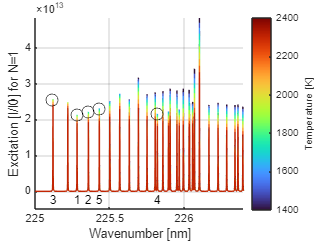

hold off
saveas(gcf, 'output-data/tempDependenceFLUO.png')